Całka oznaczona (Riemana) jest z definicji równa:

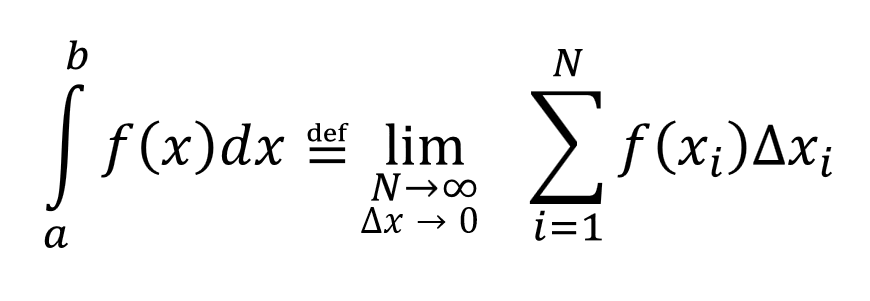

Gdzie podział przedziału (a,b) może być dowolny (byle poszczególne podprzedziały były infinitezymalnie małe). Dowolny również może być wybór konkretnego xi, dla którego obliczana będzie wartość f(xi) (byle by należał do odpowiedniego podprzedziału).

W implementacji numerycznej, gdzie wartość całki przybliża skończona suma, sposób podziału przedziału (a,b) na podprzedziały, jak i sposób obliczenia f(xi) (np. poprzez wybór xi) odgrywa kluczową rolę, ponieważ przekłada się bezpośrendio na dokładność uzyskanego wyniku (bardziej precyzyjnie mówiąc na szybkość uzyskania wyniku o założonej dokładności).

Obrazuje to następujący przykład (przyjęto równomierny podział przedziału (a,b) na podprzedziały), w różny sposób natomiast jest obliczana wartość f(xi):

clear all;
close all;
%zwybór funkcji, której będzie obliczana całka
syms f(x)
f(x)=x^3-2*x^2-5*x-3

$$f(x) = x^{3}-2\,x^{2}-5\,x-3$$

%f(x)=x^3+3/2*x^2+4*x+15/2;


N=30;
%Uruchom w domyślnym przedziale
deafVal=true

deafVal = logical
   1


 

if deafVal==true
    if strcmp(string(char(f(x))),"sin(x)")
        a=0
        b=10
    end
    if strcmp(string(char(f(x))),"x^3 - 2*x^2 - 5*x - 3")
        a=-1.5
        b=1
    end
    if strcmp(string(char(f(x))),"3*x^4 - 2*x + x^6")
        a=-1
        b=1
    end
    if strcmp(string(char(f(x))),"exp(x)")
        a=1
        b=5
    end    
    
else
    a=input("Podaj lewy kraniec przedzialu:")
    b=input("Podaj prawy kraniec przedzialu:")
    if a>=b
        disp("Prawy kraniec przedziału musi być liczbą większą od lewego krańca.")
        return
    end
end

a = -1.5000

b = 1


%%%%%%
a=0.05;
b=0.35;
f=-x.^4+6*x.^3-11*x.^2+6*x

$$f = -x^{4}+6\,x^{3}-11\,x^{2}+6\,x$$

calka_dokladna=double(int(f,a,b))

calka_dokladna = 0.2247

clear f
f = @(x) -x.^4+6*x.^3-11*x.^2+6*x

f = function_handle with value:
    @(x)-x.^4+6*x.^3-11*x.^2+6*x




%calka_dokladna=double(int(f,a,b))
%clear f
%f=@(y) y.^6+3*y.^4-2*y
%clear f
%f=@(x) x.^3+3/2*x.^2+4*x+15/2

k=3

k = 3

k=2;

Q=3;
x1=linspace(a,b,abs(b-a)*4200+1);
x3=repelem(linspace(a,b,k+1),2);
d_podprze=(b-a)/k;
pkt_l=(a:d_podprze:b-d_podprze);
pkt_r=(a+d_podprze:d_podprze:b);
pkt_m=(a+d_podprze/2:d_podprze:b-d_podprze/2);
calka_num_l(k)=sum(double(f(pkt_l)))*d_podprze;
calka_num_r(k)=sum(double(f(pkt_r)))*d_podprze;
calka_num_m(k)=sum(double(f(pkt_m)))*d_podprze;
calka_num_mv(k)=sum(double(f(pkt_l)+f(pkt_r))/2)*d_podprze;
figure()
%fill([repelem(pkt_l,2),b,b],[0,double(f(repelem(pkt_l,2))),0],'g')
%hold on
%plot(x1,double(f(x1)),pkt_l,double(f(pkt_l)),'s',pkt_r,double(f(pkt_r)),'*',pkt_m,double(f(pkt_m)),'o')
%hold off
% subplot(2,2,1)
%fill(x3,[0,double(f(repelem(pkt_l,2))),0],'g')
for i=1:numel(x3)-1
    flinie(3*i-2)=0;
    flinie(3*i-1)=f(x3(i));
    flinie(3*i)=f(x3(i));
end

%plot(repelem(x3,3),[0,flinie,0,0],'k')
%hold on
szer=round(((b-a)*4200/(k+1)));
%szer=((b-a)*100/(k+1))
f1=double(f(x1))

f1 =     0.2732    0.2744    0.2756    0.2768    0.2779    0.2791    0.2803    0.2815    0.2826    0.2838    0.2850    0.2861    0.2873    0.2885    0.2896    0.2908    0.2919    0.2931    0.2942    0.2954    0.2966    0.2977    0.2989    0.3000    0.3012    0.3023    0.3035    0.3046    0.3058    0.3069    0.3080    0.3092    0.3103    0.3115    0.3126    0.3137    0.3149    0.3160    0.3172    0.3183    0.3194    0.3206    0.3217    0.3228    0.3239    0.3251    0.3262    0.3273    0.3284    0.3296


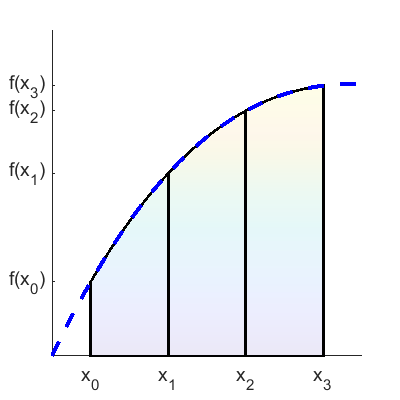


figure('position',[680,680,400,400])
plot(x1,double(f(x1)),'k')%,pkt_l,double(f(pkt_l)),'sk')
ax=gca();
hold on
x4=[];
y4=[];
for i=1:k+1
    x4=[x1(szer*i-szer+1), x1(szer*i-szer+1), x1(szer*i-szer+2:szer*i+1),x1(szer*i+1)];
    y4=[0, f1(szer*i-szer+1:szer*i+1),0];
    %colorV=[linspace(0.5,1,numel(x4));
    fill(x4,y4,y4,'linewidth',2,'facealpha',[0.1]);
end
a1=0.0;
b1=0.4;
xSpec=[0.05 0.15 0.25 0.35];
x5=linspace(a1,b1,1000);
plot(x5,f(x5),'b--','linewidth', 3)
axis([a1, b1, 0, 1.2])
xticks(xSpec)
xticklabels({'x_0','x_1','x_2','x_3'})
yticks(f(xSpec))
yticklabels({'f(x_0)','f(x_1)','f(x_2)','f(x_3)'})
ax.FontSize=14;
ax.Box='off';

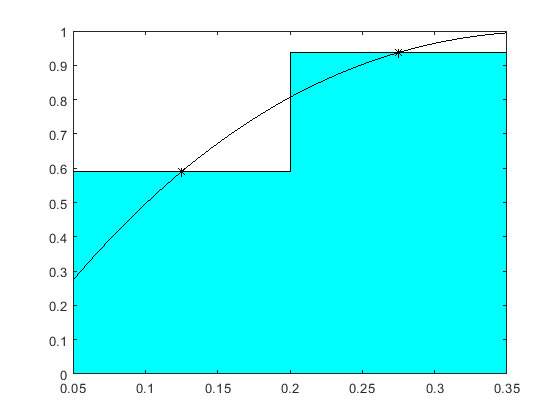


% hold off
% subplot(2,2,2)
% fill(x3,[0,double(f(repelem(pkt_r,2))),0],'r')
% hold on
% plot(x1,double(f(x1)),'k',pkt_r,double(f(pkt_r)),'ok')
% hold off
% subplot(2,2,3)
% fill(x3,[0,double(f(repelem(pkt_m,2))),0],'c')
% hold on
% plot(x1,double(f(x1)),'k',pkt_m,double(f(pkt_m)),'*k')
% hold off
% subplot(2,2,4)
% for i=1:numel(pkt_l)
%     y1(2*i-1)=pkt_l(i);
%     y1(2*i)=pkt_r(i);
% end
% fill(x3,[0,double(f(y1)),0],'y')
% hold on
% plot(x1,double(f(x1)),'k',pkt_m,double(f(pkt_l)+f(pkt_r))/2,'>k')
% hold off
%figure()
%fill(x3,[0,double(f(y1)),0],'b')
%hold on
%plot(x1,double(f(x1)),'k')
%hold off
figure()
fill(x3,[0,double(f(repelem(pkt_m,2))),0],'c')
hold on
plot(x1,double(f(x1)),'k',pkt_m,double(f(pkt_m)),'*k')
hold off




x2=Q:N;
for k=x2
    d_podprze=(b-a)/k;
    pkt_l=(a:d_podprze:b-d_podprze);
    pkt_r=(a+d_podprze:d_podprze:b);
    pkt_m=(a+d_podprze/2:d_podprze:b-d_podprze/2);
    calka_num_l(k-Q+1)=sum(double(f(pkt_l)))*d_podprze;
    calka_num_r(k-Q+1)=sum(double(f(pkt_r)))*d_podprze;
    calka_num_m(k-Q+1)=sum(double(f(pkt_m)))*d_podprze;
    calka_num_mv(k-Q+1)=sum(double(f(pkt_l)+f(pkt_r))/2)*d_podprze;
end
figure()
axRys1=axes

axRys1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


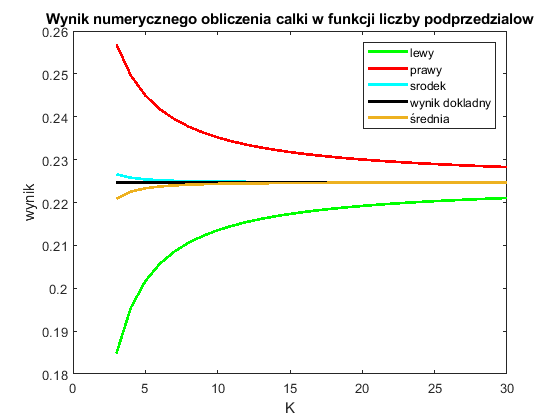

plot(x2,calka_num_l,'g',x2,calka_num_r,'r',x2,calka_num_m,'c', x2, linspace(calka_dokladna,calka_dokladna,N-Q+1),'k', 'LineWidth', 2)
hold on
axRys1.ColorOrderIndex=3;
plot(x2,calka_num_mv, 'LineWidth', 2)
%plot(x2,calka_num_l,'g',x2,calka_num_r,'r',x2,calka_num_m,'c', x2, linspace(calka_dokladna,calka_dokladna,N-Q+1),'k', 'LineWidth', 2)
title 'Wynik numerycznego obliczenia calki w funkcji liczby podprzedzialow'
xlabel 'K'
ylabel 'wynik'
legend('lewy', 'prawy', 'srodek', 'wynik dokladny', 'średnia')